# 5. 離散コサイン変換

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## 離散コサイン変換

前回の課題では，離散フーリエ変換を行った．離散フーリエ変換は，一般には複素ベクトルを入力とし，複素ベクトルを出力とする線形操作である．一方，画像，音声を含む多くの信号は，実数値であることが多い．このような場合，実数を複素数に変換すると，実数成分と虚数成分を同時に扱う必要があるため，元々の入力信号と比較し，おおよそ 2 倍の保存容量が必要となる．これは特に信号の圧縮等の応用を考えた場合好ましくない．

そこで，画像圧縮標準であるJPEGでは，以下で定義される離散コサイン変換 (discrete cosine transform: DCT) が用いられている． 


$$y[k] = \sum_{n=0}^{N-1}C_{N}[k,n] x[n]$$
  

ここで$C_N[k, n] $は以下で定義される．


$$C_N[k, n] = b(k)\sqrt{\frac{2}{N}}\cos \frac{\pi k(n + \frac{1}{2})}{N}
$$



$$b(k) = \begin{cases}
1/\sqrt{2}      &  k = 0\\
1      &  k = 1, \ldots, N-1
\end{cases}$$


定義からわかるように，DFTは**複素**正弦波で信号を展開していたが，DCTでは**実**正弦波で信号を展開することが大きな違いである．

ここで，1次元信号に対してDCTを適用してみよう．

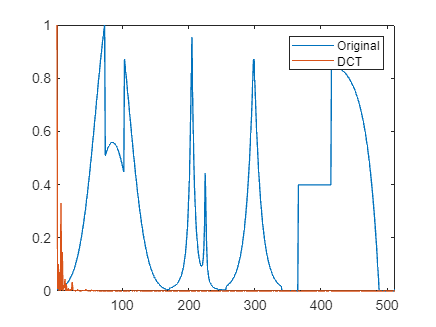

n = 512;
u = load_signal('Piece-Regular', n); % 要素数nの１次元信号
u = u(:);
u = rescale(u,0,1);
y = dct(u);
figure;
plot(1:n, [u, rescale(y.^2, 0, 1)]);
% DCT係数はエネルギー（2乗）を計算して，表示のためにスケーリングしている
axis('tight');
legend('Original','DCT') % 凡例を追加

DCTの係数$y[k]$は，$k$が小さいほど低い周波数成分に対応する．図から，信号 `Piece-Regular` は低い周波数成分にほとんどすべてのエネルギーが集中している＝信号が大域的に滑らかである ことがわかる．

DCTはDFTと同様に線形の操作である．ここで$C_N[k, n] $を$k,n$成分に持つ行列を$\mathbf{C}_N$と書くことにすると，DCTは


$$\mathbf{y} = \mathbf{C}_N\mathbf{x}$$


と表されることがわかる．$\mathbf{C}_N$は直交行列である（そのため，DCTは直交変換という変換の一種である）から，逆DCTは


$$\mathbf{x} = \mathbf{C}^{\top}_N\mathbf{y}$$


となる（$\cdot^{\top}$は行列の転置）．

## 信号の非線形近似

前回の演習で行ったフーリエ領域でのフィルタリングは，信号の**線形近似**と呼ばれる．これは，保持するインデックスを事前に（例えば低周波数成分に）固定し，その係数だけから信号を再構成することでフィルタリングを行う手法であった．

一方で，DFTやDCTの係数の振幅の大きさは，信号に含まれる周波数成分がどの程度原信号に寄与しているかを表している．そこで，変換係数を振幅の大きい順に残し，再構成することで，より良い信号の近似が得られそうである．これを**非線形近似**と呼ぶ．

実際，画像圧縮などの応用においては，非線形近似が利用されることが多い．ここで信号 `Piece-Regular` に対し，非線形近似と線形近似の結果を比較してみよう．

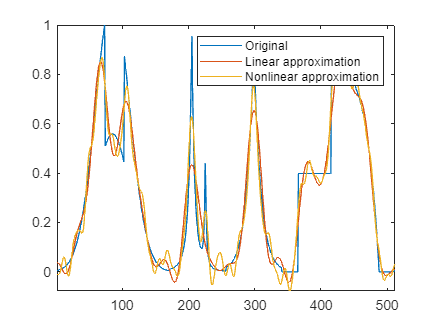

m = 32; % 原信号の1/16=6.25%の係数を残す

% 線形近似
y_lin = y;
y_lin(m+1:end) = 0;
u_lin = idct(y_lin);

% 非線形近似
y_nonlin = y;
y_sort = sort(abs(y), 'descend');
y_nonlin(abs(y_nonlin) < abs(y_sort(m))) = 0;
u_nonlin = idct(y_nonlin);

% 表示
figure;
plot(1:n, [u, u_lin, u_nonlin]);
axis('tight');
legend('Original','Linear approximation', 'Nonlinear approximation') % 凡例を追加


% 平均二乗誤差 (MSE) の計算
e_lin = sum((u-u_lin).^2)/n;
e_nonlin = sum((u-u_nonlin).^2)/n;

result_lin = sprintf('%s %.4f', 'MSE (linear) =', e_lin);
result_nonlin = sprintf('%s %.4f', 'MSE (nonlinear) =', e_nonlin);
disp(result_lin);

MSE (linear) = 0.0054


disp(result_nonlin);

MSE (nonlinear) = 0.0033


可視化された結果とMSEの双方から，非線形近似を利用したほうが優れた近似結果が得られていることがわかる．

## 演習問題

**演習5-1**: 2次元信号（画像）に対するDCTは `dct2 `で実行できる．

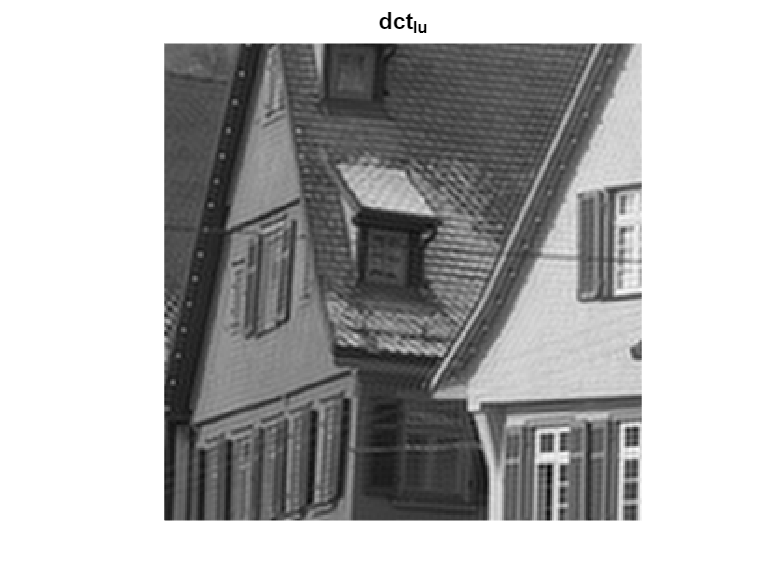

name = 'house';
u = load_image(name, []);

uc = dct2(u);
[H,W] = size(uc);
uc_lin = uc;
uc_lin(H/2+1:end,1:end) = 0;
uc_lin(1:H/2,W/2+1:end) = 0;
uic_lu = idct2(uc_lin);

figure;
imageplot(uic_lu, 'dct_lu');

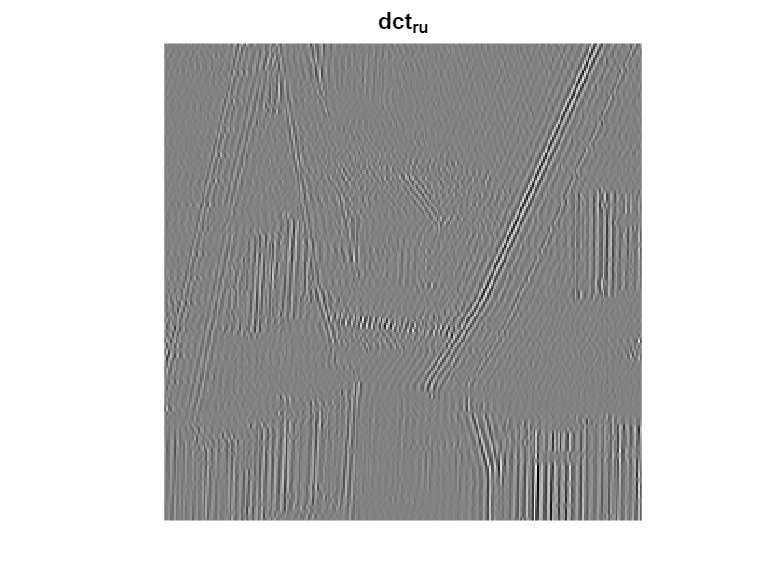


uc_ru = uc;
uc_ru(H/2+1:end,1:end) = 0;
uc_ru(1:H/2,1:W/2) = 0;
uic_ru = idct2(uc_ru);

figure;
imageplot(uic_ru, 'dct_ru');

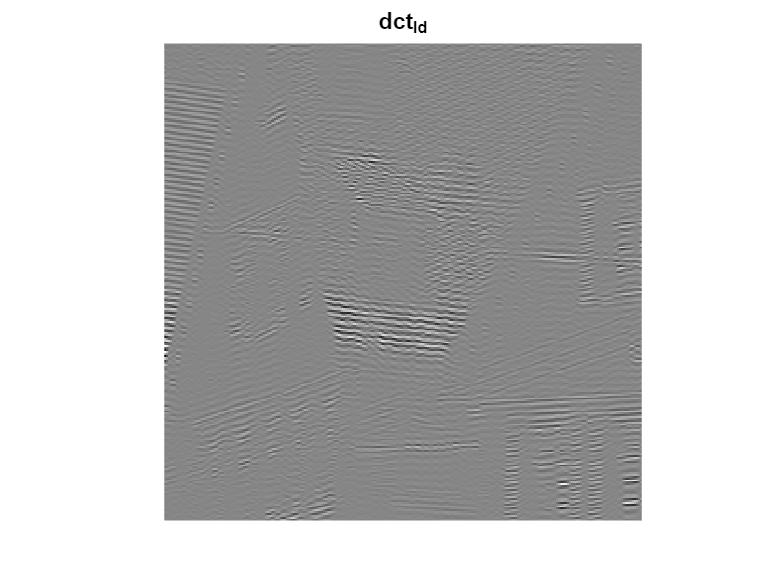


uc_ld = uc;
uc_ld(1:H/2,1:end) = 0;
uc_ld(H/2+1:end,W/2+1:end) = 0;
uic_ld = idct2(uc_ld);

figure;
imageplot(uic_ld, 'dct_ld');

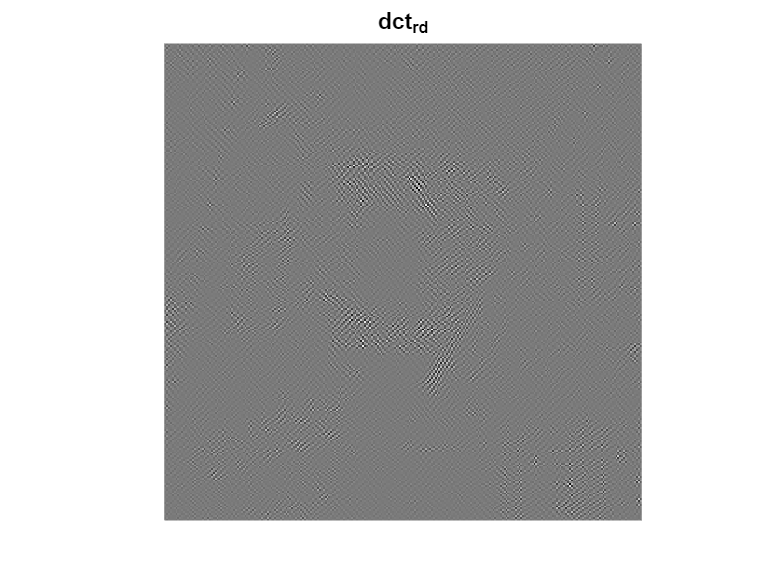


uc_rd = uc;
uc_rd(1:H/2,1:end) = 0;
uc_rd(H/2+1:end,1:W/2) = 0;
uic_rd = idct2(uc_rd);

figure;
imageplot(uic_rd, 'dct_rd');

グレースケール画像'house'を読み込み，画像に2次元DCTを行った後，以下の線形近似画像を表示せよ．

- DCT係数の左上1/4**以外**を0とした後に再構成した画像

- DCT係数の右上1/4**以外**を0とした後に再構成した画像

- DCT係数の左下1/4**以外**を0とした後に再構成した画像

- DCT係数の右下1/4**以外**を0とした後に再構成した画像

**演習5-2**: グレースケール画像'house'に対し，係数の1/16で線形近似と非線形近似を行った際の画像を表示せよ．また，PSNRを比較せよ．

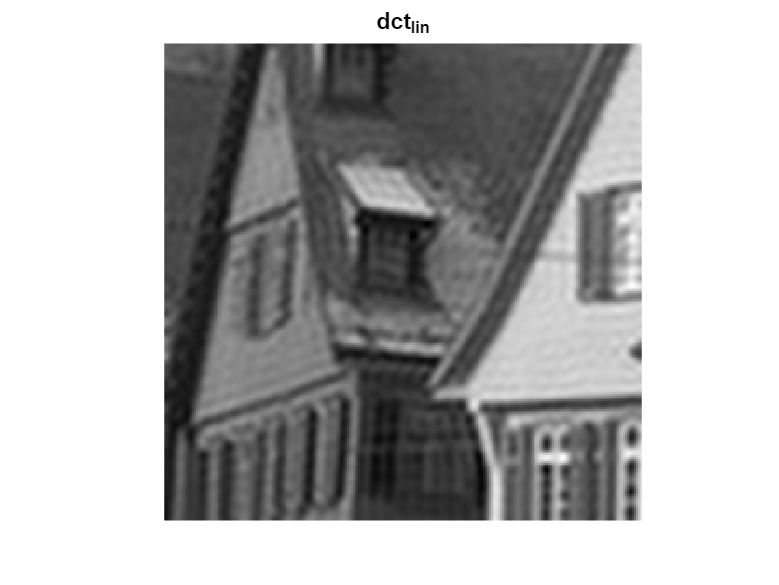

name = 'house';
u = load_image(name, []);

uc = dct2(u);
[H,W] = size(uc);
uc_lin = uc;
uc_lin(H/4+1:end,1:end) = 0;
uc_lin(1:H/4,W/4+1:end) = 0;

uic_lin = idct2(uc_lin);
figure;
imageplot(uic_lin, 'dct_lin');

result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,uic_lin), 'dB');
fprintf(result);

PSNR= 22.64 dB

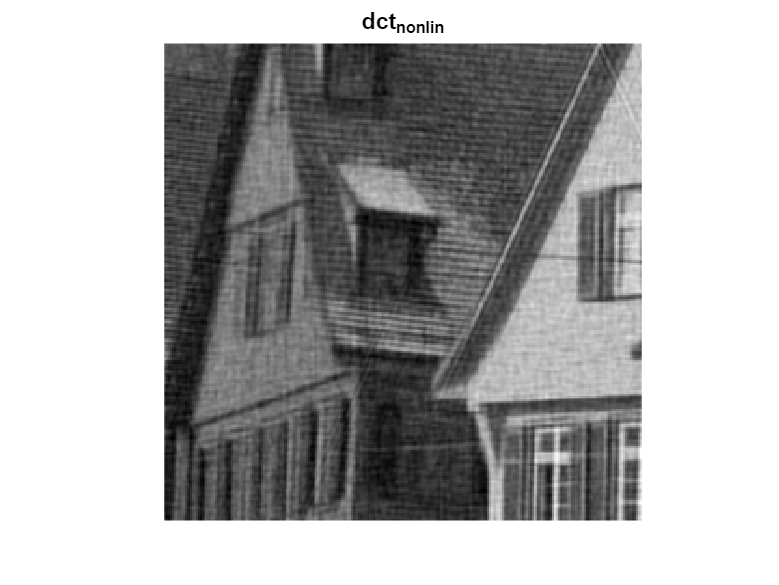


uc_nonlin = uc;
uc_sort = sort(abs(uc), 'descend');
uc_nonlin(abs(uc_nonlin) < abs(uc_sort(m))) = 0;
uic_nonlin = idct2(uc_nonlin);

figure;
imageplot(uic_nonlin, 'dct_nonlin');

result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,uic_nonlin), 'dB');
fprintf(result);

PSNR= 25.63 dB

**演習5-3**: JPEG等の画像圧縮手法では，画像全体に変換を適用するのではなく，画像を小ブロックごとに分割し，それぞれに対し（非）線形近似を行うことが多い．グレースケール画像'house'に対し，8x8画素ブロックごとに係数の1/64を残す非線形近似を行った画像を表示し，PSNRを計算せよ．

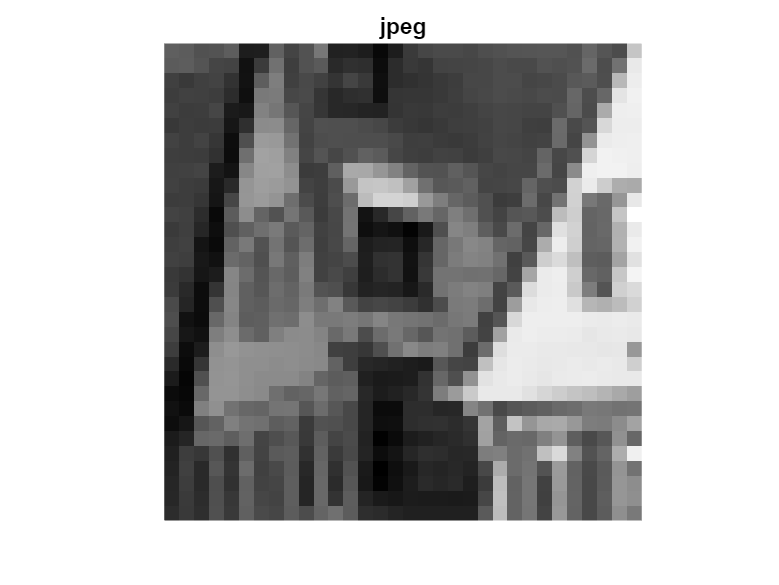

name = 'house';
u = load_image(name, []);
[H,W] = size(u);
u_jpeg = zeros(H,W);
for i = 1:H/8
    for j = 1:W/8
        block = u((i-1)*8+1:8*i,(j-1)*8+1:8*j);
        blockc = dct2(block);

        blockc_sort = sort(abs(blockc), 'descend');
        blockc_sort(1:end,2:end)=0;
        blockc_sort(2:end,1:end)=0;
        u_jpeg((i-1)*8+1:8*i,(j-1)*8+1:8*j) = idct2(blockc_sort);
    end
end

figure;
imageplot(u_jpeg, 'jpeg');

result = sprintf('%s %.2f %s', 'PSNR=', psnr(u,u_jpeg), 'dB');
fprintf(result);

PSNR= 18.78 dB